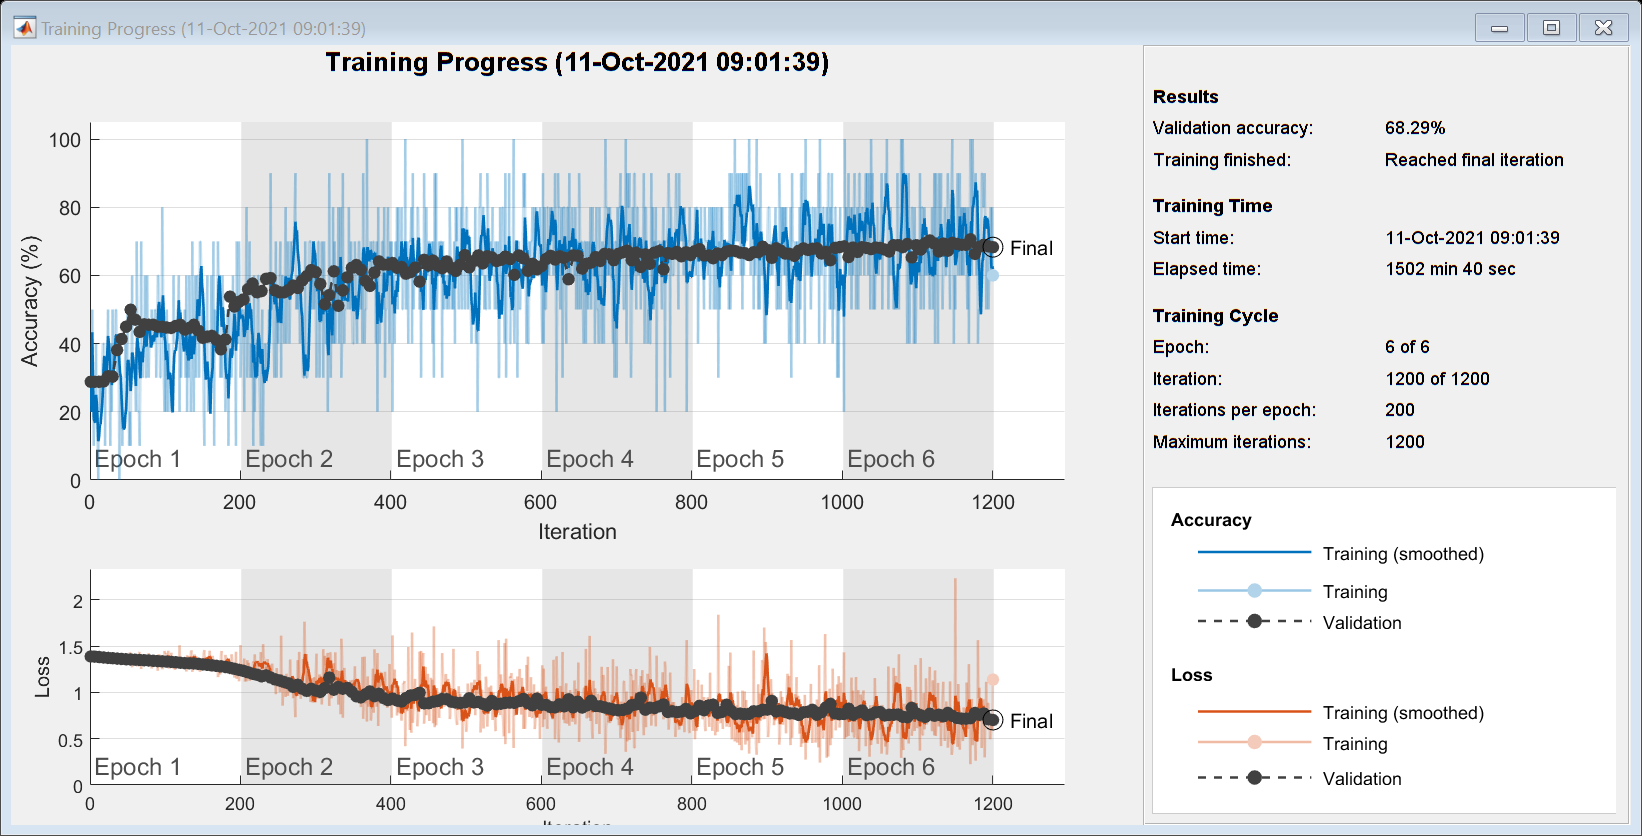

Unrecognized method, property, or field 'numLayers' for class 'SeriesNetwork'.

Error in nn.wb_indices (line 11)
hints.bInclude = false(net.numLayers,1);

Error in getwb (line 20)
if nargin < 2, hints = nn.wb_indices(net); end

addpath('C:\Users\LENOVO\OneDrive\Desktop\Materi Kuliah\Semester 7\Teknik Neurofuzi\Tugas\Deep Learning Project\Program Files\VGG19');
unzip('Training.zip');
imds = imageDatastore('Training','IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

augimdsTrain = augmentedImageDatastore([224 224],imdsTrain);
augimdsValidation = augmentedImageDatastore([224 224],imdsValidation);

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',6, ...
    'Verbose',false, ...
    'Plots','training-progress');

netTransfer = trainNetwork(augimdsTrain,layers,options);